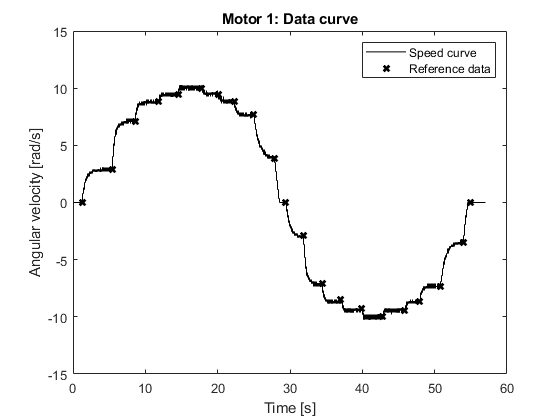

clear all
load Motor1
M1x=[];M1y0=[];

M1x(1)=1.25; M1y0(1)=0;
M1x(2)= 5.44; M1y0(2)=2.885;
M1x(3)= 8.605 ; M1y0(3)= 7.116;
M1x(4)= 11.86 ; M1y0(4)= 8.847;
M1x(5)= 14.53; M1y0(5)= 9.424;
M1x(6)= 17.75;M1y0(6)=10;
M1x(7)=20.09;M1y0(7)=9.424;
M1x(8)= 22.27;M1y0(8)=8.847;
M1x(9)= 25.02;M1y0(9)=7.693;
M1x(10)=27.87; M1y0(10)= ControlOutput(M1x(10)/0.005);
M1x(11)= 29.44; M1y0(11)=0;
M1x(12)=31.89; M1y0(12)= -2.885;
M1x(13)=34.45;M1y0(13)=-7.116;
M1x(14)= 37.03; M1y0(14)=-8.462;
M1x(15)= 39.9; M1y0(15)= -9.231;
M1x(16)= 42.8; M1y0(16)=-10;
M1x(17)=45.89; M1y0(17)= -9.424;
M1x(18)=47.94; M1y0(18)=-8.655;
M1x(19)= 50.83;M1y0(19)=-7.308;
M1x(20)=53.98; M1y0(20)=-3.462;
M1x(21)=55;M1y0(21)=0;
stairs(X_Value,ControlOutput,'k')
hold on
plot(M1x,M1y0,'xk','LineWidth',2)
xlabel('Time [s]')
ylabel('Angular velocity [rad/s]')
title('Motor 1: Data curve')
legend('Speed curve','Reference data')
hold off


M1tamano=length(M1x)-1;
M1escalon=cell(M1tamano,2);
for i=1:M1tamano
    aux=(ControlOutput(M1x(i)/0.005));
    M1escalon{i,2}= ControlOutput(M1x(i)/0.005:M1x(i+1)/0.005)-aux;
    M1escalon{i,1}= linspace(0,M1x(i+1)-M1x(i),length(M1escalon{i,2}));
end
M1k=[];
M1Tao=[];
M1Wc=[];
M1idx=[];
M1Funcion=cell(M1tamano,1);
M1Filtro=cell(M1tamano,1);

for i=1:M1tamano
    M1k(i)=mean(M1escalon{i,2}(end-100:end))-M1escalon{i,2}(1);
    [na,aux1]=min(abs(M1escalon{i,2}-0.63*M1k(i)));
    [na,aux2]=min(abs(M1escalon{i,2}-0.28*M1k(i)));
    M1Tao(i)=1.5*(M1escalon{i,1}(aux1)-M1escalon{i,1}(aux2));
    M1Wc(i)=M1Tao(i)/10;
    M1Funcion{i,1} = tf(M1k(i),[M1Tao(i),1]);
    
%     filtro
    M1Filtro{i,1} = tf(1,[M1Wc(i),1]);
end
M1k , M1Tao 

M1k =     2.8810    4.3168    1.4815    0.5960    0.6131   -0.4970   -0.5256   -1.2015   -3.7950   -3.8465   -3.0086   -4.1207   -1.3901   -0.5408   -0.7921    0.6017    0.5179    1.3520    3.6408    3.4199


M1Tao =     0.3600    0.3075    0.2175    0.0900    0.0375    0.1725    0.0975    0.1950    0.5325    0.3525    0.4650    0.2475    0.1425    0.0675    0.1950    0.0825    0.1500    0.1725    0.5475    0.3075


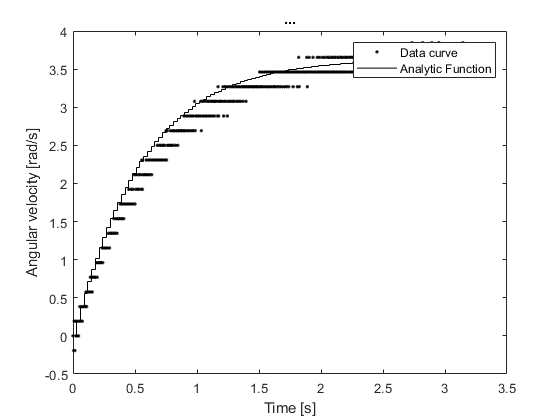

M1graficar=19;
plot(M1escalon{M1graficar,1},M1escalon{M1graficar,2},'.k')
hold on
[M1yAux,M1xAux]=step(M1Funcion{M1graficar},3);
stairs(M1xAux,M1yAux,'k')
xlabel('Time [s]')
ylabel('Angular velocity [rad/s]')
title('...')
legend('Data curve','Analytic Function')
hold off


M1T=0.005;
% 

M1Filtrodigital=cell(M1tamano,1);
M1numfiltrodigital=zeros(M1tamano,1);
M1denfiltrodigital=zeros(M1tamano,1);

for i=1:M1tamano
    M1Filtrodigital{i,1} = c2d(M1Filtro{i,1},M1T);
    
    M1numfiltrodigital(i)=M1Filtrodigital{i}.num{1}(end);
    M1denfiltrodigital(i)=M1Filtrodigital{i}.den{1}(end);
end


aplicando el filtro

ecuacion en diferencias

y_k=num*x_k-1+den*y_k-1


M1Y=cell(M1tamano,1);

for j=1:M1tamano
M1y=[0];

aux1 = M1escalon{j,1};
aux2 = M1escalon{j,2};

for i=2:length(aux2) %para y valor actual comienza en 2
    M1y(i)=M1numfiltrodigital(j)*aux2(i-1)-M1denfiltrodigital(j)*M1y(i-1);
end

M1Y{j}=M1y;
end

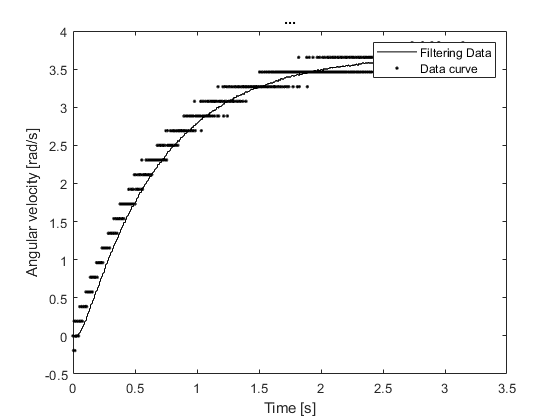


stairs(M1escalon{M1graficar,1},M1Y{M1graficar},'k')
hold on
plot(M1escalon{M1graficar,1},M1escalon{M1graficar,2},'.k')  % al aplicar el filtro se agrega un retardo
xlabel('Time [s]')
ylabel('Angular velocity [rad/s]')
title('...')
legend('Filtering Data','Data curve')
hold off

Errores

    M1Error2medio=(M1Y{M1graficar}'-M1escalon{M1graficar,2})'*(M1Y{M1graficar}'-M1escalon{M1graficar,2})/length(M1escalon{M1graficar,1})

M1Error2medio = 0.0185

    for i=1:M1tamano
    M1Error2medios(i)=(M1Y{i}'-M1escalon{i,2})'*(M1Y{i}'-M1escalon{i,2})/length(M1escalon{i,1});
    end
    M1Error2medios

M1Error2medios =     0.0111    0.0201    0.0132    0.0162    0.0233    0.0145    0.0164    0.0124    0.0207    0.0218    0.0172    0.0173    0.0132    0.0172    0.0136    0.0161    0.0135    0.0106    0.0185    0.0240


% Tabla=cell(M1tamano,5);

% for i=1:tamano
%     Tabla{i,:} = table(i,mat2str(Funcion,mat2str([Funcion{i}.den{1}]),Wc(1),Error2medios(i)));
% end
